actividad realidadaen la clase de la sesión 10

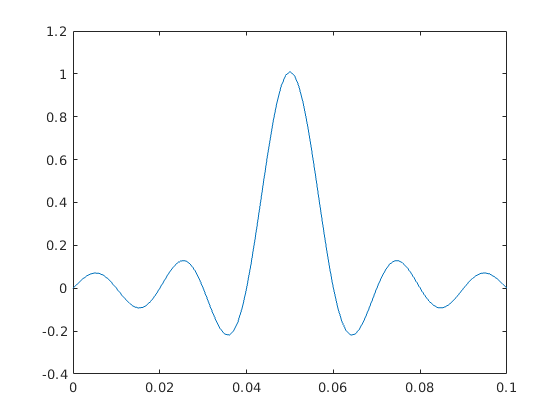

beta=0; fs=1000; Tp=1/100; D=10;
type = 'rc';
Ts=1/fs;
energy =Tp;
[p t] = rcpulse(beta,D,Tp,Ts,type,energy);
plot(t,p)

e = Ts*p*p'

e = 0.0100


bits = [1 0 1 1 0 0 1 1 1 1 1]

bits =      1     0     1     1     0     0     1     1     1     1     1


sym = bits*2-1

sym =      1    -1     1     1    -1    -1     1     1     1     1     1


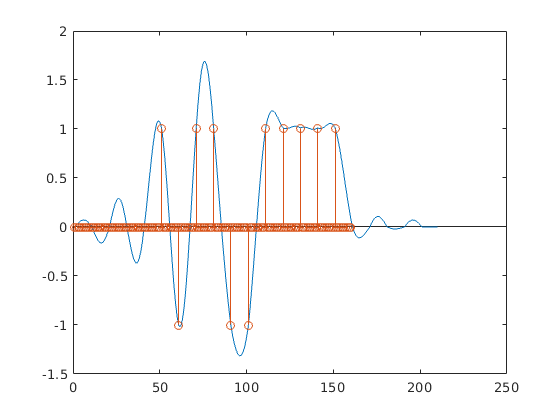

mp = Tp/Ts;
s = zeros(1,numel(bits)*mp);
s(1:mp:end) = sym;
xnrz = conv(p, s);
plot(xnrz)
hold on;
stem([zeros(1,50) s])

hold off;

beta=0; fs=1000; Tp=1/100; D=10;
type = 'srrc';
Ts=1/fs;
energy =Tp;
[p t] = rcpulse(beta,D,Tp,Ts,type,energy);
plot(t,p)

e = Ts*p*p'

e = 0.0100


bits = [1 0 1 1 0 0 1 1 1 1 1]

bits =      1     0     1     1     0     0     1     1     1     1     1


sym = bits*2-1

sym =      1    -1     1     1    -1    -1     1     1     1     1     1


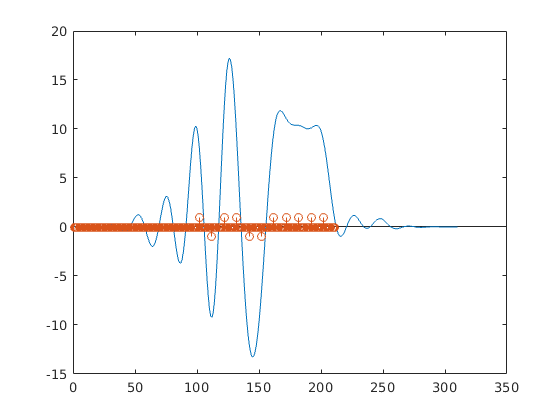

mp = Tp/Ts;
s = zeros(1,numel(bits)*mp);
s(1:mp:end) = sym;
xnrz = conv(p, s);
xnrz_Rx = conv(p, xnrz);
plot(xnrz_Rx)
hold on;
stem([zeros(1,101) s])